# Yahu's Cone Detector

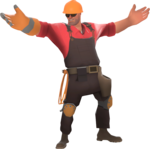

Eliyahu Suskind, 3/28/2023, Rev 1.

% Clean Up Before Running CV
clc
clear
close all

% User select mode
myMode = input("Enter 0 for NN mode, 1 for pixel mode: ")

myMode = 0


% Initiate webcam and set balance mode
camList = webcamlist

camList = 2×1 cell array
    {'BisonCam, NB Pro'             }
    {'Microsoft® LifeCam Cinema(TM)'}


roboCam = webcam(2)

roboCam =   webcam with properties:

                     Name: 'Microsoft® LifeCam Cinema(TM)'
     AvailableResolutions: {'640x480'  '640x360'  '424x240'  '352x288'  '320x240'  '176x144'  '160x120'  '1280x720'  '960x544'  '800x448'  '800x600'}
               Resolution: '640x480'
         WhiteBalanceMode: 'auto'
                 Contrast: 5
                      Pan: 0
                FocusMode: 'auto'
               Brightness: 100
                Sharpness: 25
                     Zoom: 0
                     Tilt: 0
                    Focus: 2
             ExposureMode: 'auto'
                 Exposure: -6
    BacklightCompensation: 0
               Saturation: 83
             WhiteBalance: 4500


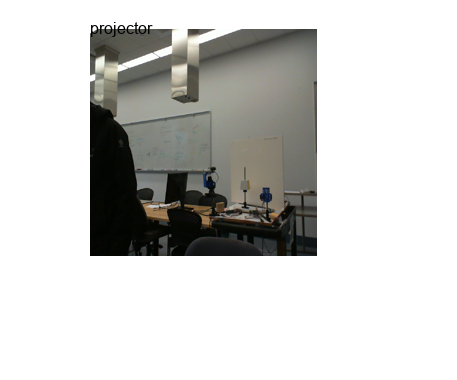

roboCam.WhiteBalanceMode = "manual";
roboCam.Brightness = 100;
myNN = alexnet;

% Create imshow for image handling
if myMode == 0
camShow = imshow(zeros(277, 277, 3, 'uint8'));
end
if myMode == 1
camShow = imshow(zeros(480, 640, 3, 'uint8'));
hold on
currPlot = plot(0, 0, 'b*');
currText = text(0, 0, '');
hold off
end

% Initialize frames
frames = 2000;
oldLabel = "";
currFrameLabel = text(0,0,"");


% Run Live Cam
for i = 1:frames
    
    % NN Mode
    if myMode == 0
    label = nn_detector(roboCam, myNN, camShow);
    if oldLabel ~= label
        delete(currFrameLabel);
        oldLabel = label;
        currFrameLabel = text(0,0,label);
    end
    end

    % Pixel Mode
    if myMode == 1
        [cleanImage, centroid, robotImage] = pixel_detector(roboCam);
        overlay = imoverlay(robotImage, cleanImage, [1 0 0]);
        set(camShow,'CData',overlay);
        drawnow;
        
        hold on
        delete(currPlot);
        delete(currText);
        currPlot = plot(centroid(:,1), centroid(:,2), 'b*')
        currText = text(centroid(:,1), centroid(:,2), 'Centroid');
        hold off
    end

end

function label = nn_detector(roboCam, myNN, camShow)

    % Capture and classify current frame 
    currFrame = roboCam.snapshot;
    currFrameFin = imresize(currFrame,[227 227]);
    label = classify(myNN,currFrameFin);

    % Draw current frame and label
    set(camShow,'CData',currFrameFin);
    drawnow;

end

function [cleanImage, centroid, robotImage] = pixel_detector(roboCam1)

% Create filtered webcam image, prompt user input
robotImage = snapshot(roboCam1);
[targetMask, ~] = orangeMask(robotImage);
clc;

% Fill noise in filtered image
preYahuObjects = regionprops('table',targetMask, 'area');
YahuObjects = table2array(preYahuObjects);
preCleaner = max(YahuObjects);
myCleaner = preCleaner - 1;
cleanImage = bwareaopen(targetMask, myCleaner);

% Find centroid
targetCenter = regionprops(cleanImage, 'centroid');
centroid = cat(1, targetCenter.Centroid);
clc;

end